Simple simulation of the chemostat. The setup is the full NUM model.

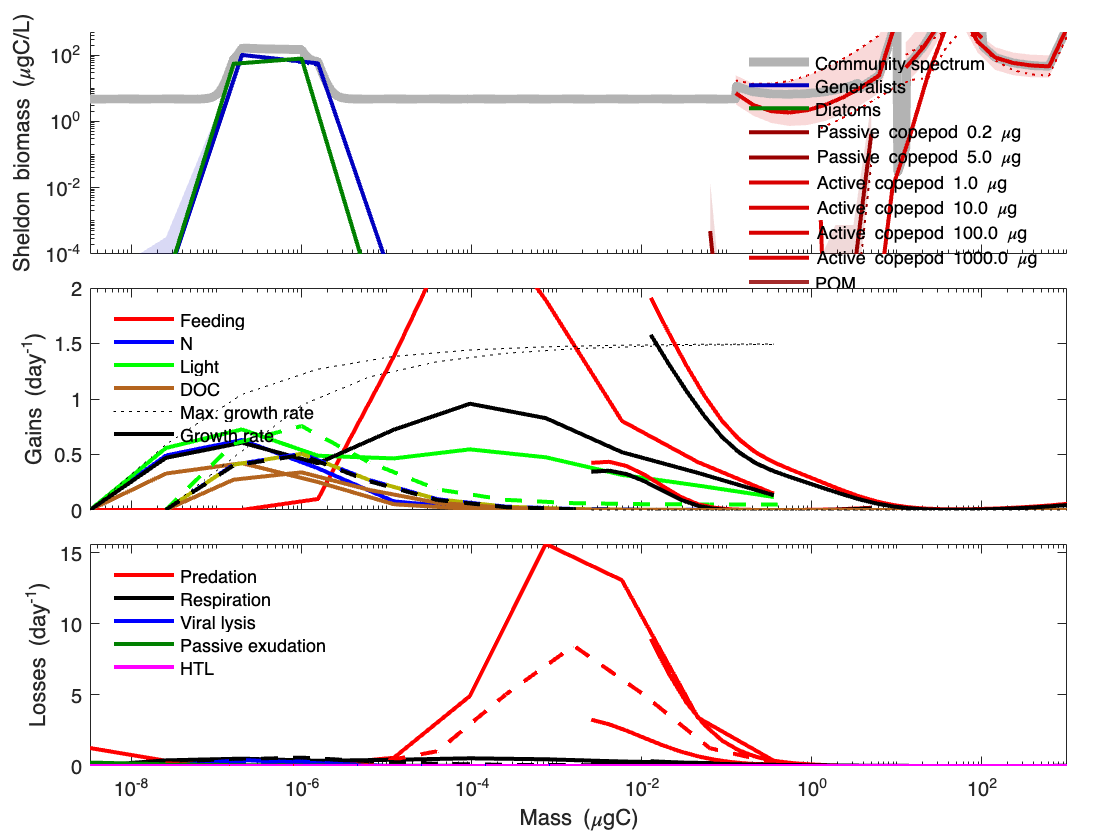


Light = 100;
Mixing = -0.8;
mHTL = -2.4;

p = parametersChemostat( setupNUMmodel );
p.tEnd = 1000;

p.d = 10^Mixing;
setHTL(10^mHTL);

sim = simulateChemostat(p, L, 10);

plotSizespectrum(sim);

sim = calcFunctions(sim, bPrintSummary=true);

----------------------------------------------
Final total biomass:  99311.431 mgC/m2
Final Chl:              15.142 gChl/m2
Final gross PP:       7570.879 mgC/m2/day
Final net PP:         1920.705 mgC/m2/day
Final net bact prod.: 2052.901 mgC/m2/day
Final HTL production:  345.621 mgC/m2/day
----------------------------------------------
